**Writing Analysis Functions for SchwartzLab DataJoint**

One of the most important goals in the SchwartzLab Datajoint implementation was to make writing analysis functions as simple as possible. A shortcoming of our old analysis functions was that they were build inside MATLAB classes thta required quite a bit of background knowledge of object-oriented programming and a bunch of tree structures and other complex code that I wrote and documented poorly or not at all. This created a large energy barrier to writing new analyses within this system, and many people chose to work outside it instead.

This time it will be different! You should all be writing your own functions to analyze your data, and I want to help you learn how. Analysis functions in the new system are not classes; they are functions with exactly 3 inputs (one of them being optional) and one output struct. 

Step 1. Decide your "level"

Like other aspects of our DataJoint implementation, analysis functions work on either Epochs, Datasets, Cells, or across Cells. So You need to decide which is right for your analysis function. Remember, pieplines are build from a sequence of analyses, so you will need to break the work down into parts that can be done on each level. An Epoch level analysis function only has access to one Epoch at a time, so everything you need to compute your result should be at that level. The same is true for each higher level. At the highest level, Multi-Cell analyses can combine results across Cells and Datasets however you like. 

Step 2. Write the first line

Here is the first line of an example analysis function on the Epoch level:

It has 3 inputs at one output, as follows:

**Inputs**

**Output**

Step 3. Decide whether you want parameters and what results you want

Of course you can change these decisions as you write the function, but it's good to go in with a plan. This particular function has no parameters, but here is a similar one that does: 

So, if I want to use the value of the first time interval in my analysis, I would call

Name your parameters anything you like, but be sure to document it at the top of the function in a comment like this.

Back to the spikesInPreStimPost function, here are the final lines that set the outputs

The variable 'sp' is a vector of spike times, and I will show you below how it is set. But for now, the point is just to see how you set your results in the return struct R. Give them informative names because these will also become the variable names in the hdf5 files you export to Igor.

I recommend writing these "R.result_field =" lines and commenting them out before you even start writing the guts of your function. That way, the goal is right there in front of you to help you stay organized. It is good practice to document all the outputs of your function in a comment at the top as well.

Step 4. Grab the pieces of information you need from the Epoch/Dataset/Cell

This is where the "fetch" command will become your friend. See the Overview document for details about how to use it. In this example, I want to get the preTime, stimTime, tailTime, and sample_rate from the 'protocol_params' struct inside the current epoch.

Sometimes the piece of data you need will not be stored in the Epoch/Dataset/Cell itself, but in an associated entry from another table in the database. Examples include the SpikeTrain associated with an Epoch or the CurrentCellType entry that stores the type of a Cell. For these kinds of data, you will need to use queries. Let's look at an example from this analysis function to grab the SpikeTrain associated with an epoch.

Since each Epoch should be associated with a single SpikeTrain (or none), we can use 'fetch1' here. It will return an error if the SpikeTrain has not been imported (or you call it on a voltage-clamp epoch), so we can put in a check for that error.

**Using getStoredResult**

As you go up the "level" hierarchy in your analysis pipeline, you will likely need to grab results from lower levels. For example, *SMS_spike_analysis* is a Dataset level function for SpotsMultiSize datasets that relies on spike counts computed for individual Epochs using *spikesInPreStimPost*. In these cases, instead of searching through the database yourself with queries, I made a utility function that will look through the database for you to grab the Results that you are looking for. The function is called *getStoredResults* and it has 2 required parameters and one optional parameter.

The search key is what the database uses to figure out which results to return to you. So if you only want one result, you need to be specific. The search key is a struct. Let's continue with this example in *SMS_spike_analysis*. 

Step 5. Perform your computation and store the results. 

How this looks really depends on what your analysis function is trying to do. For the Epoch function, *spikesInPreStimPost,* the computation is very simple. Once the data from the epoch is extracted, the spike counts are one-liners as shown above.

In other cases, you will collect a bunch of results, do something like fit a curve to that data, and then store the parameters of the curve fit. If you have gotten this far and really understand the code in this example, you know enough to write your own analysis functions. However, I have made a few utilities that you might find useful. You can see how they are used in context in *SMS_spike_analysis.*

Analysis Utility Functions

**getExampleProtocolParametersForEpochInDataset**

This function with kind of an absurdly long, but descriptive name, returns both the 'protocol_params' struct from the first Epoch belonging to the specified Dataset and the names of all the protocol_params fields for which the value changes across Epochs in the Dataset. For example, in most of our MovingBar datasets, the barLength and barSpeed are constant, but the barAngle changes for each epoch. 

**distributeAndOrder**

This one should really come in handy because it captures an analysis motif we use often. *keyVector* is a vector of all the values for a key parameter that you want to use to group and sort the data in the all the vectors in *otherVals_struct.* For example, in *SMS_spike_analysis*, *keyVector* holds the spotSize for each Epoch, and *otherVals_struct* holds the corresponding spike rates in the Pre, Stim, and Post periods for each epoch. The *distributeAndOrder* function finds all the unique values of spotSize, sorts them, groups the Epochs belonging to each spotSize value, and returns the mean, standard deviation, standard error of the mean, and number of samples for each of these spike rates for each spotSize. 

I put an example of soome of this data from an SMS Dataset in the Documentation folder. Load it and take a look.

load distributeAndOrder_example.mat;
spotSize

spotSize =    314
   614
   858
   160
   439
    82
   115
    30
   224
    59


computedVals

computedVals = struct with fields:
     spikeRatePre: [36×1 double]
    spikeRateStim: [36×1 double]
    spikeRatePost: [36×1 double]


There are 36 epochs; each has a spotSize, and the three spikeRates. What we want is an ordered list of spotSizes with the mean (and s.d., s.e.m, and N) for the epochs at each spot size. This is what *distributeAndOrder* does.

outputStruct = distributeAndOrder(spotSize, computedVals)

outputStruct = struct with fields:
                  keyVals: [12×1 double]
                    key_N: [12×1 double]
                  key_ind: [12×36 double]
        spikeRatePre_mean: [12×1 double]
         spikeRatePre_sem: [12×1 double]
          spikeRatePre_sd: [12×1 double]
     spikeRatePre_N_noNaN: [12×1 double]
       spikeRateStim_mean: [12×1 double]
        spikeRateStim_sem: [12×1 double]
         spikeRateStim_sd: [12×1 double]
    spikeRateStim_N_noNaN: [12×1 double]
       spikeRatePost_mean: [12×1 double]
        spikeRatePost_sem: [12×1 double]
         spikeRatePost_sd: [12×1 double]
    spikeRatePost_N_noNaN: [12×1 double]


And there are similar fields for the other rates. This is enough information to plot the standard SMS curve that we all know and love.

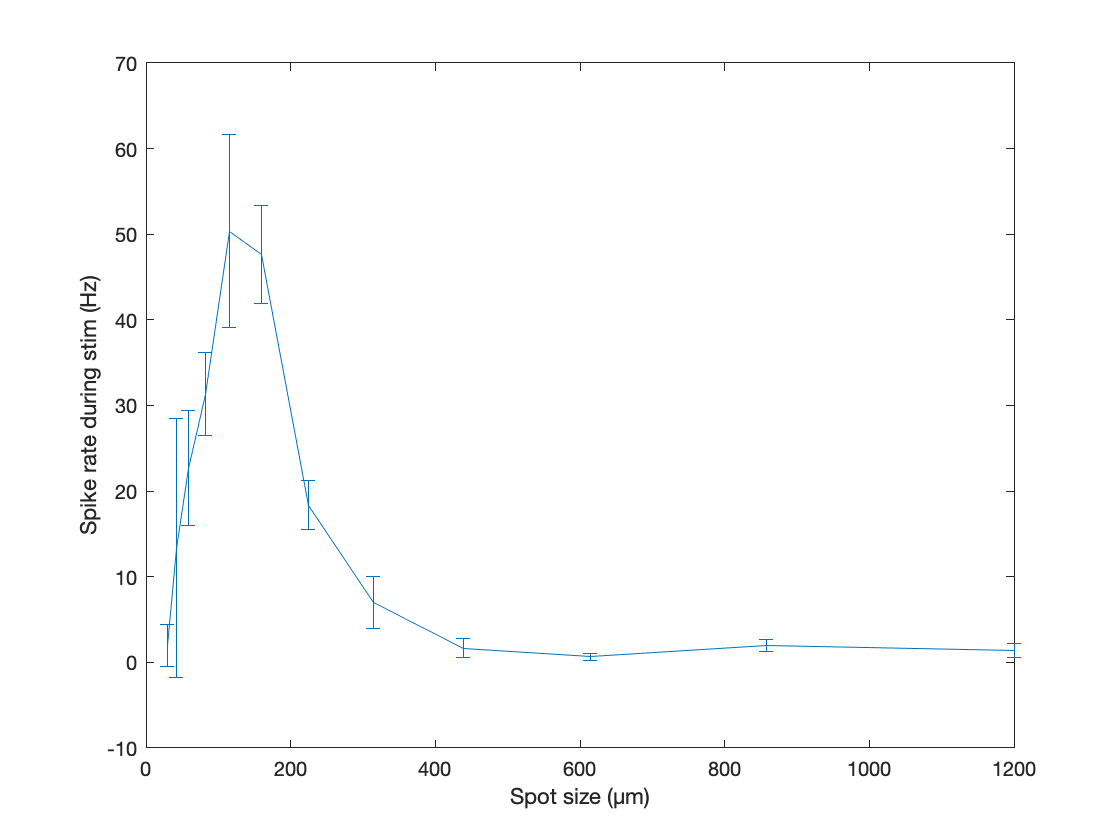

errorbar(outputStruct.keyVals, outputStruct.spikeRateStim_mean, outputStruct.spikeRateStim_sem);
xlabel('Spot size (μm)');
ylabel('Spike rate during stim (Hz)');

**epochRawData**

This function is pretty self-explanatory. It will grab the data from an epoch or set of epochs from a single cell. The 'channel' parameter is optional and defaults to 1. It is there in case you need to grab channel 2 from paired reordings. The returned time axis is in units of seconds with the stimulus onset time set to zero. Remeber, you need the raw data file in your 'raw_data' folder.

**psth**

This function will return the peri-stimulus-time-histogram (PSTH) of a set of epochs from a single cell. Only the first two inputs (cell_id and epoch_numbers) are required. The rest have default values. 

**cellID_to_dateAndRig**

A simple litte function to return the date and rig from a cell_id like '051320Ac1'